# Fundamentals of Linear Control

**Mauricio de Oliveira**

*Supplemental material for Chapter 2*

## Before You Start

In this script you will continue to perform basic calculations and plotting data. In addition to the commands already used, the following MATLAB commands will be used:

- `ode45` and `deval,` to solve a differential equation (more about that on Chapter 5);

 You will also use the following auxiliary commands:

- `array2table`, to create a table object for nicely displaying an array.

## 2.3 Dynamic Response

Plot the values of the response:


$$y(t) = \bar{y} \, (1 - e^{-\lambda t}) + y_0 \, e^{\lambda t}$$


for various values of $\lambda$ and $y_0$:

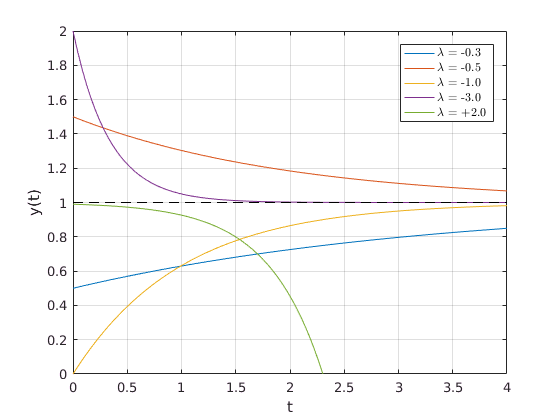

ybar = 1;
T = 4;
N = 5;
bsy0s = [.3 .5; .5 1.5; 1. 0; 3. 2; -2 .99];

t = linspace(0,T,100);
y = zeros(N,length(t));
for i = 1 : N;
  b = bsy0s(i, 1);
  y0 = bsy0s(i, 2);
  y(i,:) = ybar * (1 - exp(-b * t)) + y0 * exp(-b * t);
end

% Fig. 2.4:
figure()
plot(t, y, [0 T], ybar*[1 1], 'k--');
xlabel('t')
ylabel('y(t)')

leg = [char(ones(N, 1) * double('$\lambda$ = ')) num2str(-bsy0s(:,1),'%+2.1f~')];
h = legend(leg, 'Location', 'NorthEast');
set(h, 'Interpreter', 'latex')

ylim([0 2])
grid

## 2.4 Experimental Dynamic Response

Load the car data once again:

% load data for dynamic car model
load CarModel

and average the last 15 samples to obtain an estimate of $p/b=\tilde{y}/\tilde{u}$:

% linear fit
N = length(td);
T = td(N);
uTilde = 1;

% fit ybar to last 15 points
NTilde = 15;
yTildeHat = mean(vd(N-NTilde:N));
pOverBHat = yTildeHat / uTilde;
pOverBHat = round(pOverBHat,1) % round

pOverBHat = 73.3000

Then estimate $\lambda$ by fitting a line to the function $r(t) = 1 - \frac{y(t)}{\tilde{y}} $:

% fit lambda to first 11 points
Nlambda = 11;
r = (yTildeHat - vd) ./ yTildeHat;
r = r(1 : Nlambda);
lr = log(r);
tr = td(1 : Nlambda);

lambdaHat = lr / tr;
lambdaHat = round(lambdaHat,2) % round

lambdaHat = -0.0500

bOverMHat = - lambdaHat

bOverMHat = 0.0500

pOverMHat = bOverMHat * pOverBHat;
pOverMHat = round(pOverMHat,2) % round

pOverMHat = 3.6700

The resulting fit can be visualized on the plot:

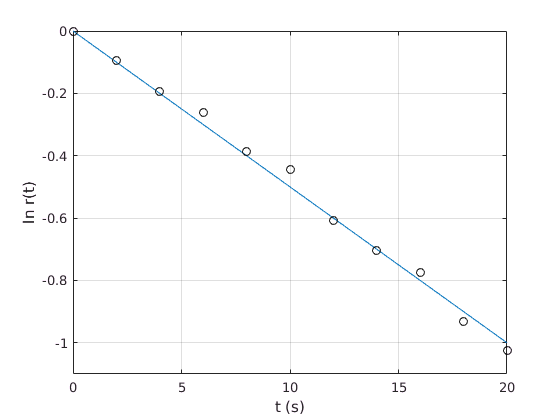

% Fig 2.6: 
figure()
plot([0 tr(end)], lambdaHat * [0 tr(end)], tr, lr, 'ok');
xlabel('t (s)')
ylabel('ln r(t)')
ylim([-1.1 0])
grid

Plot the complete fit along with the data:

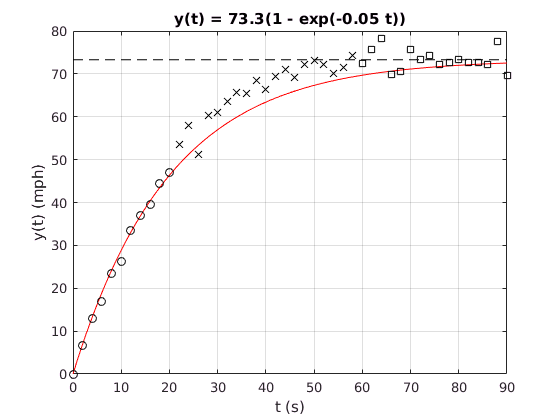

tl = linspace(0,T,100);
yl = yTildeHat * (1 - exp(lambdaHat*tl));

% Fig 2.5: 
figure()
plot(tl, yl, 'r', ...
  td(N-2*NTilde-4:N-NTilde-1), vd(N-2*NTilde-4:N-NTilde-1), 'kx', ...
  td(N-NTilde : N), vd(N-NTilde : N), 'ks', ...
  td(1:N-2*NTilde-5), vd(1:N-2*NTilde-5), 'ko',...
  [0 T], pOverBHat*[1 1], 'k--');
xlabel('t (s)')
ylabel('y(t) (mph)')
title(['y(t) = ' num2str(pOverBHat,3) '(1 - exp(' num2str(lambdaHat, 2) ' t))'])
ylim([0 80])
grid

## 2.5 Dynamic Feedback Control

Calculate the open- and closed-loop figures of the response of the linear car model to a constant target velocity of $\bar{y} = 60$mph:

% response to constant target velocity
yBar = 60

yBar = 60

N = 4;
ks = [0 0.02 0.05 0.5];

taus = zeros(N,1);
yTildes = zeros(N,1);
Hs = zeros(N,1);

% open loop
uBar = yBar / pOverBHat;
yTilde = pOverBHat * uBar;

yTildes(1) = yTilde;
taus(1) = 1/bOverMHat;
Hs(1) = 1;

% closed loop
for i = 2 : N;
  bb = bOverMHat + pOverMHat * ks(i);
  yTilde = yBar * pOverMHat * ks(i) / (bOverMHat + pOverMHat * ks(i));

  yTildes(i) = yTilde;
  taus(i) = 1/bb;
  Hs(i) = yTilde / yBar;
end

% Table 2.1: Linear closed-loop gains
mat = [ks' Hs 1-Hs yTildes taus log(9)*taus];
colNames = {'K','H0','S0','yTilde','tau','tr'};
array2table(mat, 'VariableNames', colNames)

ans =      K        H0          S0       yTilde     tau        tr  
    ____    _______    ________    ______    ______    ______

       0          1           0        60        20    43.944
    0.02    0.59481     0.40519    35.689    8.1037    17.806
    0.05    0.78587     0.21413    47.152    4.2827      9.41
     0.5    0.97347    0.026525    58.408    0.5305    1.1656


Calculate the complete response and associated control inputs: 

T = 30;
cs = ['g';'r';'b';'m'];

t = linspace(0,T,100);
y = zeros(N,length(t));
u = zeros(N, length(t));

% open loop
y(1,:) = yTildes(1) * (1 - exp(-bOverMHat * t));
u(1,:) = uBar * ones(size(t));

% closed loop
for i = 2 : N;
  y(i,:) = yTildes(i) * (1 - exp(-bb * t));
  u(i,:) = ks(i) * (yBar - yTildes(i) * (1 - exp(-bb * t)));
end

then plot the responses:

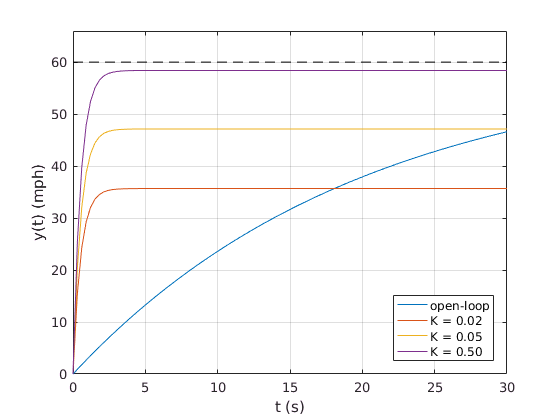

% Fig. 2.8
figure()
plot(t, y, [0 T], yBar*[1 1], 'k--');
xlabel('t (s)')
ylabel('y(t) (mph)')

leg = [char(ones(N, 1) * double('K = ')) num2str(ks','%3.2f') char(ones(N, 1) * double(' '))];
leg(1,:) = 'open-loop';
legend(leg, 'Location', 'SouthEast')

ylim([0 1.1*yBar])
grid on

and the inputs:

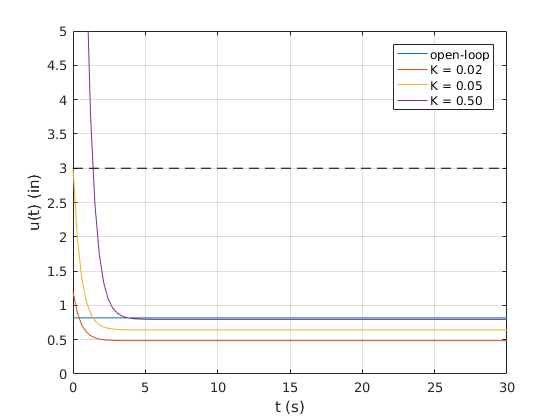

% Fig. 2.9:
figure()
uMax = 3;
plot(t, u, [0 T], uMax*[1 1], 'k--');
xlabel('t (s)')
ylabel('u(t) (in)')
legend(leg, 'Location', 'NorthEast')
ylim([0 5])
grid on

## 2.6 Nonlinear Models

First estimate the relavant quantities for the nonlinear model:

% model fitting
alpha = 82.8

alpha = 82.8000

beta = 1.2

beta = 1.2000


cOverMHat = alpha * bOverMHat;
cOverMHat = round(cOverMHat,1) % round

cOverMHat = 4.1000

dOverMHat = beta * cOverMHat;
dOverMHat = round(dOverMHat,1) % round

dOverMHat = 4.9000

dOverCHat = dOverMHat / cOverMHat;
dOverCHat = round(dOverCHat,1) % round

dOverCHat = 1.2000

Calculate the complete response and associated control inputs using MATLAB's ode45 to simulate the nonlinear model: 

ynl = {};
unl = {};
t = linspace(0,T,100);

The open-loop nonlinear model is:


$$\dot{y}(t) = f(y(t), t) = \frac{d}{m} \mathrm{sat}_{(0,3)}(u(t)) - \frac{c}{m} \tan \frac{y(t)}{\alpha}, \qquad u(t) = \bar{u}$$


which you simulate as follows:

uBar = tan(yBar/alpha)/beta;                        % open-loop control
f = @(t,y) dOverMHat*uBar - cOverMHat*tan(y/alpha); % @ creates function on the fly
sol = ode45(f, [0 T], 0);                           % solve ode
ynl{1} = deval(sol, t);                             % evaluate solution 
unl{1} = uBar * ones(size(t));                      % u(t) = uBar

The closed-loop nonlinear model is:


$$\dot{y}(t) = f(y(t), t) = \frac{d}{m} \mathrm{sat}_{(0,3)}\left ( K(\bar{y} - y(t)) \right ) - \frac{c}{m} \tan \left (\frac{y(t)}{\alpha}\right )$$


which you simulate as follows:

for i = 2 : N
    f = @(t,y) dOverMHat*min([uMax,ks(i)*(yBar-y)])-cOverMHat*tan(y/alpha);
    sol = ode45(f, [0 T], 0);          % solve ode
    ynl{i} = deval(sol, t);            % evaluate solution
    unl{i} = ks(i) * (yBar - ynl{i});  % calculate u(t)
    unl{i}(unl{i} > 3) = 3;            % saturate u(t)
end

Plot the responses:

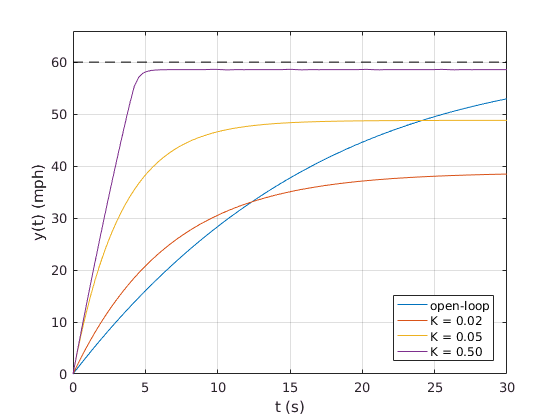

% Fig. 2.10
figure()
plot(t, ynl{1}, ...
     t, ynl{2}, ...
     t, ynl{3}, ...
     t, ynl{4}, ...
     [0 T], yBar*[1 1], 'k--');
xlabel('t (s)')
ylabel('y(t) (mph)')
legend(leg,'Location','SouthEast')
ylim([0 1.1*yBar]);
grid

and the inputs:

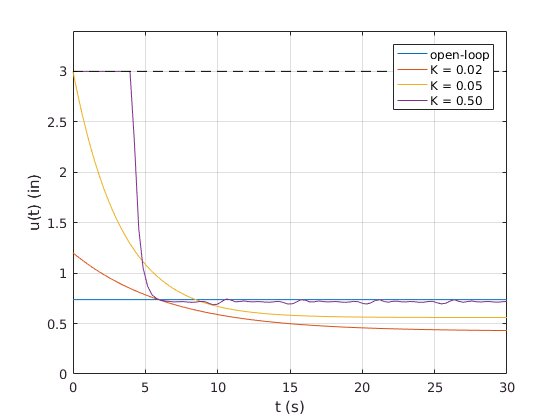

% Fig. 2.11
figure()
plot(t, unl{1}, ...
     t, unl{2}, ...
     t, unl{3}, ...
     t, unl{4}, ...
     [0 T], uMax*[1 1], 'k--');
xlabel('t (s)')
ylabel('u(t) (in)')
ylim([0 3.4]);
legend(leg,'Location','NorthEast')
grid

## 2.7 Disturbance Rejection

Calculate the response of the linear car model to a change in slope (disturbance) from 0% to 10% slope:

% Closed- and open-loop disturbance response
G = 9.8 * 3600 / 1609; % unit conversion yuck!
yBar = 60;
thetaBar = atan(.1) % 10% slope

thetaBar = 0.0997

wBar = -G/pOverMHat * sin(thetaBar)

wBar = -0.5945


T0 = 10;
T = 50;
t = linspace(0,T,200);

tt = [-T0 0 t];
yy = zeros(N, length(tt));

% open loop
lambda = -bOverMHat;
G0 = pOverMHat/bOverMHat;
yy(1,:) = [yBar; yBar; yBar + (1-exp(lambda*t'))*G0*wBar];

% closed loop
for i = 2 : N;
  Kp = ks(i);
  H0 = Kp*pOverMHat/(bOverMHat+Kp*pOverMHat);
  D0 = pOverMHat/(bOverMHat+Kp*pOverMHat);
  lambda = -bOverMHat-pOverMHat*Kp;
  yy(i,:) = [H0*yBar; H0*yBar; H0*yBar+(1-exp(lambda*t'))*D0*wBar];
end

then plot the responses:

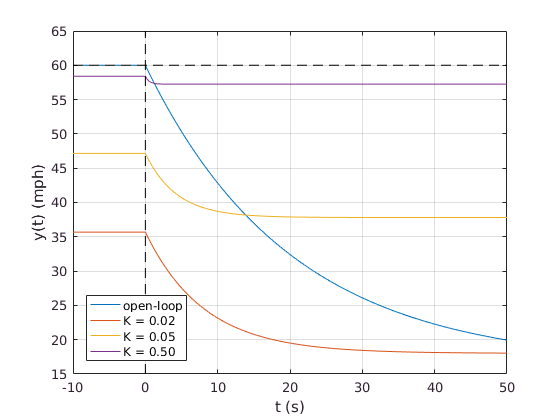

% Fig. 2.14:
figure()
plot(tt, yy, [-T0 T], yBar*[1 1], 'k--', [0 0], 2*yBar*[0 1], 'k--')
xlabel('t (s)')
ylabel('y(t) (mph)')
legend(leg,'Location','SouthWest')
ylim([15 yBar+5])
grid on